data = readtable('/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/COVID/CC_COVID/Confirmed_Cases_CC.csv', 'ReadVariableNames',1);

%dates = readtable('/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/COVID/CC_COVID/Confirmed_Cases_CC.csv');

Confounding = readtable('/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/Confounding/Confounding_Dataset.csv', 'ReadVariableNames',1);
Total_Population = (Confounding.TOT_POP);

cases = table2array(data(:,12:173));
cases = cases./Total_Population;

% dates = table2array(dates(1,[12:173]));
% dates = datetime(dates, 'Format', 'dd/MM/yy'); 

splines = zeros(842,1024);
derivatives = zeros(842,1024);
double_derivatives = zeros(842,1024);

for t = 1:842
    casesS = cases(t,:);
    casesS = nonzeros(casesS); % non-zero cases 
    if length(casesS)>1
        x = [1:length(casesS)]';  % number of days since first case 
        f = fit(x, casesS, 'smoothingspline');
        xeval = linspace(1, length(casesS), 1024);
        sp_eval = f(xeval)';
        splines(t,:)= sp_eval;
        
        [fx, fxx] = differentiate(f, xeval);
        derivatives(t,:)=fx';
        double_derivatives(t,:) = fxx';  
    end 
end 

clf;
i = 333; 

derivatives1 = derivatives(:,[1:256]);
D1_m = mean(derivatives1(i,:));
derivatives2 = derivatives(:,[257:512]);
D2_m = mean(derivatives2(i,:));
derivatives3 = derivatives(:,[513:768]);
D3_m = mean(derivatives3(i,:));
derivatives4 = derivatives(:,[769:1024]);
D4_m = mean(derivatives4(i,:));

DSum = sum([D1_m, D2_m, D3_m, D4_m]);
D1_mN = D1_m/DSum

D1_mN = 0.4441

D2_mN = D2_m/DSum

D2_mN = 0.3297

D3_mN = D3_m/DSum

D3_mN = 0.1763

D4_mN = D4_m/DSum

D4_mN = 0.0500


x = [1:1024]

x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


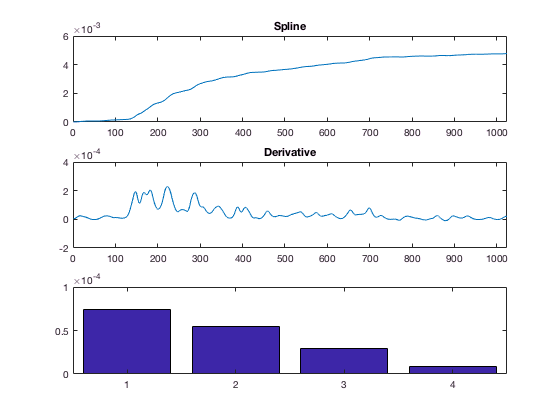

figure(1)
subplot(3,1,1)
plot(x,splines(i,:))
xlim([0,1024])
title('Spline')
subplot(3,1,2)
plot(x,(derivatives(i,:)))
xlim([0,1024])
title('Derivative')
subplot(3,1,3)
X = categorical({'1st Quarter', '2nd Quarter', '3rd Quarter', '4th Quarter'});
X = reordercats(X,{'1st Quarter', '2nd Quarter', '3rd Quarter', '4th Quarter'});
Y = [D1_mN, D2_mN, D3_mN, D4_mN]
YM = zeros(size(Y));
[~, idx] = max(Y);
YM(idx) = Y(idx);

hold on; 
b = bar(X,Y,'FaceColor',[0 0.4470 0.7410]);
bM = bar(X, YM, 'FaceColor', [0.4660 0.6740 0.1880]);
hold off; 

bar(X,Y)

%histogram(abs(derivatives(i,:)))
%plot(x,(double_derivatives(i,:)))
%xlim([0,1024])
%title('Double Derivative')
